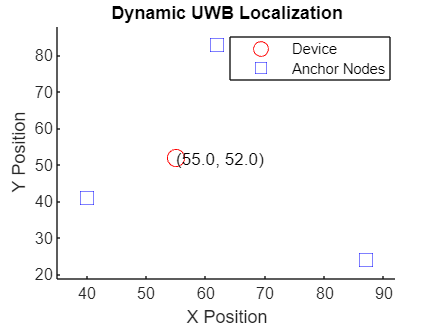

% Define initial positions for device and anchor nodes
deviceLocInitial = [50 50];  % Initial device position
nodeLocInitial = [40 41;     % Initial anchor node positions
                  62 83;
                  87 24];

% Define velocity for device (change as needed)
deviceVelocity = [0.5, 0.2];   % Velocity of the device in x and y directions

% Simulation parameters
numTimeSteps = 100;  % Number of time steps for simulation
timeStep = 0.1;      % Time step duration (adjust as needed)

% Initialize device and anchor node positions
deviceLoc = deviceLocInitial;

% Initialize plot variables
figure;
hold on;
xlabel('X Position');
ylabel('Y Position');
title('Dynamic UWB Localization');
axis tight;

% Initialize plot limits
minX = min([deviceLocInitial(1), nodeLocInitial(:, 1)']);
maxX = max([deviceLocInitial(1), nodeLocInitial(:, 1)']);
minY = min([deviceLocInitial(2), nodeLocInitial(:, 2)']);
maxY = max([deviceLocInitial(2), nodeLocInitial(:, 2)']);
margin = 5; % Margin for zooming
axis([minX-margin maxX+margin minY-margin maxY+margin]);

% Plot initial positions of device and anchor nodes
devicePlot = plot(deviceLocInitial(1), deviceLocInitial(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'Device');
nodePlot = plot(nodeLocInitial(:, 1), nodeLocInitial(:, 2), 'bs', 'MarkerSize', 10, 'DisplayName', 'Anchor Nodes');

% Initialize text annotation for device coordinates
deviceText = text(deviceLocInitial(1), deviceLocInitial(2), sprintf('(%.1f, %.1f)', deviceLocInitial), 'HorizontalAlignment', 'left');

% Main simulation loop
for t = 1:numTimeSteps
    % Update device position
    deviceLoc = deviceLoc + deviceVelocity * timeStep;
    
    % Update plot positions
    set(devicePlot, 'XData', deviceLoc(1), 'YData', deviceLoc(2));
    
    % Update text annotation for device coordinates
    set(deviceText, 'Position', [deviceLoc(1), deviceLoc(2)], 'String', sprintf('(%.1f, %.1f)', deviceLoc));
    
    % Draw plot
    drawnow;

    % Pause for visualization (optional)
    pause(0.1);
end

% Add legend
legend('Location', 'best');